Αυτός ο κώδικας είναι παράδειγμα χρήσης του Hantek 6022BL σαν Logger,

δίνοντας τις μετρήσεις του ως τιμές αντί να τους εκτυπώνει στην οθόνη, 

κάνοντάς τον χρήσιμο σε εφαρμογές που θέλουμε να πέρνουμε μετρήσεις και να τις επεξεργαστούμε στο matlab!

Πριν τρέξετε το παρακάτω script, πρέπει να:

- Έχετε συνδεδεμένο το Hantek 6022 BL

- Tρέχει το HantekProxy.exe

- Να έχετε τα cpp αρχεία που καλούνται εδώ, στο Current Folder

- Κάνεις pause execution εκεί που λέει το comment (line 35)

% Hantek 6022BL MATLAB Interface - Updated Version
% Make sure HantekProxy.exe is running first!
clear all
close all

Θέλει δουλειά ακόμη. Πρέπει να 

- Εντολή που το βάζει σε loop μετρήσεων για να μην έχει χρονικά κενά. Να τα στέλνει το ένα μετά το άλλο σε pipeline

bufferSize = 1e5;           % max buffer size = 1049584
DEVICE_INDEX = uint16(0);       % First connected device
DEVICE_TYPE = uint16(1);        % 0=Hantek6022BL, 1=Hantek6022BE
SAMPLE_RATE = int16(0);         % 3 = 4MSa/s (see dsoSetTimeDIV docs)
BUFFER_SIZE = uint32(bufferSize);     % Number of samples to capture
NUM_CAPTURES = 2;              % For continuous acquisition
SamplingRate= SamplingLUT(SAMPLE_RATE);

#### Initilize & Configure Device 

InitHantek6022(DEVICE_INDEX, DEVICE_TYPE, SAMPLE_RATE)

HantekProxy.exe is already running
Library loaded successfully. Available functions:

Functions in library HantekWrapper:

int32 connectToProxy
disconnectFromProxy
uint16 dsoChooseDevice(uint16, int16)
int16 dsoOpenDevice(uint16)
[int16, int16Ptr, int16Ptr] dsoReadHardData_LA(uint16, int16Ptr, int16Ptr, ulong, int32)
int16 dsoSetTimeDIV(uint16, int32)



Initializing device...
Device is open. Ready for use


      100000



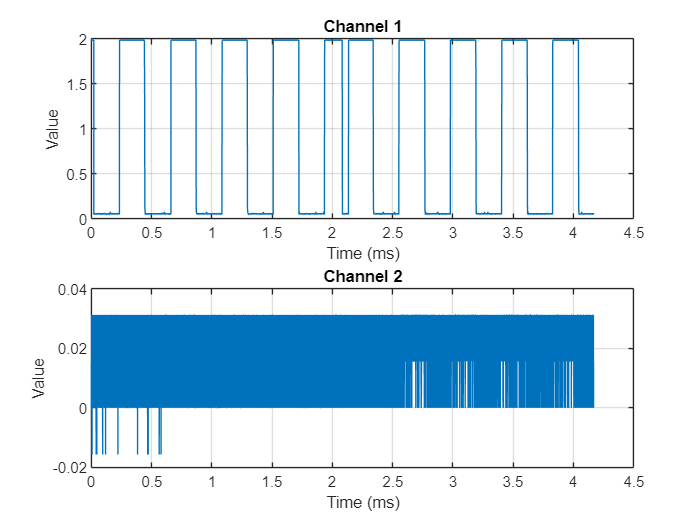


Capture Statistics:
  Total captures: 2
  Samples per capture: 100000
  CH1 Range: [4.687500e-02, 1.984375e+00]
  CH2 Range: [-1.562500e-02, 3.125000e-02]


try
    % Preallocate storage for multiple captures
    data = struct(...
        'time', zeros(BUFFER_SIZE, NUM_CAPTURES), ...
        'ch1',  zeros(BUFFER_SIZE, NUM_CAPTURES), ...
        'ch2',  zeros(BUFFER_SIZE, NUM_CAPTURES));
    
    % Capture loop
    hWait = waitbar(0, 'Capturing data...');
    for i = 1:NUM_CAPTURES
        % Create MATLAB-compatible buffers
        ch1 = libpointer('int16Ptr', zeros(BUFFER_SIZE, 1, 'int16'));
        ch2 = libpointer('int16Ptr', zeros(BUFFER_SIZE, 1, 'int16'));
        
        % Capture data
        samples = calllib('HantekWrapper', 'dsoReadHardData_LA', ...
            DEVICE_INDEX, ch1, ch2, BUFFER_SIZE, SAMPLE_RATE);
        
        if samples == -1
            error('Capture failed on iteration %d', i);
        end
        
        % Store data with timestamp
        time_offset = 0;
        if i>1
            time_offset = data.time(BUFFER_SIZE,i-1);
        end
        data.time(:,i) = (0:double(BUFFER_SIZE)-1)/(1e-3*SamplingRate) + time_offset; % in ms
        data.ch1(:,i) = (double(ch1.Value) - 128)/2^6;
        data.ch2(:,i) = (double(ch2.Value) - 128)/2^6;
        
        waitbar(i/NUM_CAPTURES, hWait, sprintf('Capture %d/%d', i, NUM_CAPTURES));
    end
    close(hWait);
    AnalyzeData(data);
    
catch ME    % Comprehensive error reporting
    fprintf('\nERROR: %s\n', ME.message);
    for st = ME.stack'
        fprintf('  In %s (line %d)\n', st.name, st.line);
    end
end

#### Clean up

stopHantekProxy

function AnalyzeData(data)
    figure('Name', 'Hantek 6022BL Data', 'NumberTitle', 'off');
    
    % Plot first capture
    subplot(2,1,1);
    disp(length(data.ch1(:,1)))
    plot(reshape(data.time, [],1), reshape(data.ch1, [],1));
    title('Channel 1');
    xlabel('Time (ms)');
    ylabel('Value');
    grid on;
    
    subplot(2,1,2);
    plot(reshape(data.time, [],1), reshape(data.ch2, [],1));
    title('Channel 2');
    xlabel('Time (ms)');
    ylabel('Value');
    grid on;
    
    % Statistics
    fprintf('\nCapture Statistics:\n');
    fprintf('  Total captures: %d\n', size(data.ch1, 2));
    fprintf('  Samples per capture: %d\n', size(data.ch1, 1));
    fprintf('  CH1 Range: [%d, %d]\n', min(data.ch1(:)), max(data.ch1(:)));
    fprintf('  CH2 Range: [%d, %d]\n', min(data.ch2(:)), max(data.ch2(:)));
end


#### startHantekProxy

- *Starts the HantekProxy.exe application*

- *loads the HantekWrapper.dll library*

function startHantekProxy() 
    flagEXE = 0;
    flagDLL = 0;
    [status, cmdout] = system('tasklist /FO CSV /FI "IMAGENAME eq HantekProxy.exe"');
    if ~status && contains(cmdout, "PID")
        fprintf("HantekProxy.exe is already running\n");
    else
        system('start /B HantekProxy.exe');
        flagEXE = 1;
    end
    if libisloaded('HantekWrapper')
        fprintf("Library already loaded");
    else
        [notfound, warnings] = loadlibrary('HantekWrapper.dll', 'HantekWrapper.h');
        if ~isempty(notfound)
            error('Missing critical functions: %s', strjoin(notfound, ', '));
        end
        if ~isempty(warnings)
            warning('Library warnings:\n%s', strjoin(warnings, '\n'));
        end
        flagDLL = 1;
    end

    pause(0.8);
    if flagEXE
        [status, cmdout] = system('tasklist /FO CSV /FI "IMAGENAME eq HantekProxy.exe"');
        if ~status && contains(cmdout, "PID") % the .exe is open
            fprintf('Hantek proxy started\n');
        else
            fprintf("Could not start HantekProxy.exe\n");
        end
    end
    if flagDLL
        if libisloaded('HantekWrapper')
            fprintf('Library loaded successfully. Available functions:\n');
            libfunctions('HantekWrapper', '-full');
        else
            fprintf("Could not load the HantekWrapper Library\n")
        end
    end
end

#### stopHantekProxy

- *Terminates connection with HantekProxy.exe*

- *Terminates the HantekProxy.exe application*

- *Unloads the library*

function stopHantekProxy() % closes the the .dll and Proxy.exe
    flagEXE = 0;
    flagDLL = 0;
    [status, cmdout] = system('tasklist /FO CSV /FI "IMAGENAME eq HantekProxy.exe"');
    if ~status && contains(cmdout, "PID") % the .exe is open
        calllib('HantekWrapper','disconnectFromProxy');
        system('taskkill /IM HantekProxy.exe /F');
        flagEXE = 1;
    else
        fprintf('The HantekProxy wasnt open or found.\n')
    end

    if libisloaded('HantekWrapper')
        unloadlibrary('HantekWrapper');
        flagDLL = 1;
    else
        fprintf('the library wasnt open or found\n')
    end

    if flagEXE
        [status, cmdout] = system('tasklist /FO CSV /FI "IMAGENAME eq HantekProxy.exe"');
         if ~status && ~contains(cmdout, "PID") % the .exe is open
             fprintf("HantekProxy Teminated successfully\n");
         else
             fprintf("Could not terminate the HantekProxy.exe\n")
         end
    end
    if flagDLL
        if ~libisloaded('HantekWrapper')
            fprintf('HantekWrapper.dll unloaded\n');
        else
            fprintf("Could not unload the HantekWrapper Library\n")
        end
    end
end

#### InitHantek6022

- *Connects to the HantekProxy.exe application*

- *Opens a connection with the instrument (6022)*

- *Selects the oscilloscope (set DEVICE_TYPE to 0 for data analyzer)*

- *Sets the Sampling Rate*

function InitHantek6022(DEVICE_INDEX, DEVICE_TYPE, SAMPLE_RATE)
    try     % Load library with verbose error reporting
        startHantekProxy();
        fprintf('\nInitializing device...\n');
        calllib('HantekWrapper', 'connectToProxy');
        calllib('HantekWrapper', 'dsoOpenDevice', DEVICE_INDEX);
        calllib('HantekWrapper', 'dsoChooseDevice', DEVICE_INDEX, DEVICE_TYPE);
        pause(0.8);
        calllib('HantekWrapper', 'dsoSetTimeDIV', DEVICE_INDEX, SAMPLE_RATE);
        fprintf('Device is open. Ready for use\n');
    catch ME    % Comprehensive error reporting
        fprintf('\nERROR: %s\n', ME.message);
        for st = ME.stack'
            fprintf('  In %s (line %d)\n', st.name, st.line);
        end
    end
end

function samplingRate = SamplingLUT(timeDiv)
    % Sampling rate lookup table for Hantek 6022BL
    % Based on the time division settings
    switch timeDiv
        case 0
            samplingRate = 48000000; % 48 MSa/s
        case 1
            samplingRate = 16000000; % 16 MSa/s
        case 2
            samplingRate = 8000000;  % 8 MSa/s
        case 3
            samplingRate = 4000000;  % 4 MSa/s
        case 4
            samplingRate = 1000000;  % 1 MSa/s
        case 5
            samplingRate = 500000;   % 500 kSa/s
        case 6
            samplingRate = 200000;   % 200 kSa/s
        case 7
            samplingRate = 100000;   % 100 kSa/s
        otherwise
            samplingRate = 4000000;  % Default 4 MSa/s
    end
end